# МЕТОДЫ ОПТИМИЗАЦИИ

## Семинар 7

### Системы линейных алгебраических уравнений

Решим систему линейных уравнений:

### Линейная оптимизация

#### Полиномиальная оптимизация

Полиномиальный фиттинг  - частный случай линейной оптимизации

Пусть $\vec t = \matrix {t_1 \cr \vdots \cr t_N}$ - вектор независиммых переменных, полиномиальная функция имеет вид:


$$\vec y (\vec t)= a_1 \vec  {t}^0 +\vec{t}^1 + ... + \vec{t}^{P-1} =[\matrix {1 & \dots & t_1^{i-1} & \dots &t_1^{P-1} \cr  \vdots & & \vdots & & \vdots \cr 1 & \dots & t_j^{i-1}& \dots & t_j^{P-1} \cr   \vdots & & \vdots & & \vdots \cr t_j^{i-1}& \dots & t_j^{P-1} & \dots & t_{N}^{P-1} } ] [\matrix{a_1 \cr \vdots \cr a_i \cr \vdots \cr a_P}] = V\vec{a}$$


$V$ - матрица Вандермонда - матрица размером [NxP], $\vec{a}$ - вектор параметров линейной оптимизации.

Если число измеренных точек (N) больше числа коэффициентов полинома, то, данная переопределенная система имеет решение в форме псевдообратной матрицы $\vec{a}$.

N=100

N = 100

t = transpose(linspace(-1,1,N))

t =    -1.0000
   -0.9798
   -0.9596
   -0.9394
   -0.9192
   -0.8990
   -0.8788
   -0.8586
   -0.8384
   -0.8182


P = 5

P = 5

a1=1;
a2=1.992;
a3=0.554;
a4=0.0218;
a5=-0.55829;
e = 0; % амплитуда шумов 
a_real = [a1;a2;a3;a4;a5];
% заполняем массив "экспериментальных" данных
y = 0;
for ii = 0:P-1
    y = y + a_real(ii+1)*t.^ii;
end
y = y + e*randn(size(y));

% решаем задачу
Pf = 2

Pf = 2

V = vandermatrix(t,Pf); % формируем матрицу Вандермонда
tb = table();
tb.a_real = a_real(1:Pf);
tb.a_fitted_qr = V\y; % решается методом qr факторизации

tb.a_fitted_pinv= pinv(V)*y;
tb.a_lsqr = lsqminnorm(V,y) ;
a_polyfit = transpose(polyfit(t,y,Pf-1)); 
tb.a_polyfit = a_polyfit(end:-1:1);
tb

tb = 2×5 table
    a_real    a_fitted_qr    a_fitted_pinv    a_lsqr    a_polyfit
    ______    ___________    _____________    ______    _________

        1       1.0722          1.0722        1.0722     1.0722  
    1.992       2.0053          2.0053        2.0053     2.0053  


ax = get_next_ax();

fig1


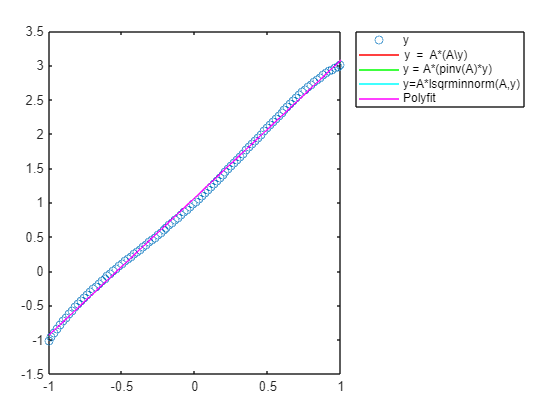

plot(ax,t,y,"o")
hold(ax,"on");
    plot(t,V*tb.a_fitted_qr,'r')
    plot(t,V*tb.a_fitted_pinv,'g')
    plot(t,V*tb.a_lsqr,'c')
    plot(t,V*tb.a_polyfit,'m')
hold(ax,"off")
legend(ax,["y" "y = A*(A\\y)" "y = A*(pinv(A)*y)" "y=A*lsqrminnorm(A,y)" "Polyfit"],Location="bestoutside")

Сравнение скорости решения:

tm = table();
tm.t_fitted_qr = timeit(@()V\y,1); % решается методом qr факторизации
tm.t_fitted_pinv= timeit(@()pinv(V)*y,1);
tm.t_lsqr = timeit(@()lsqminnorm(V,y),1) ;
tm.t_polyfit = timeit(@()polyfit(t,y,Pf-1),1);
tm

tm = 1×4 table
    t_fitted_qr    t_fitted_pinv      t_lsqr      t_polyfit 
    ___________    _____________    __________    __________

    3.8316e-05      7.5169e-05      7.8169e-05    0.00014927


#### Оценка погрешности полиномиальной аппроскимации

#### Полиномиальный фиттинг в матлаб

#### Оптимизация ортогональными полиномами

### Нелинейная оптимизация без ограничений

#### Методы, использующие информацию с предудыщей итерации 

function V = vandermatrix(t,P)
% создаем матрицу Вандермонда
    t = t(:);
    V = t.^(0:1:P-1);
end
function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end